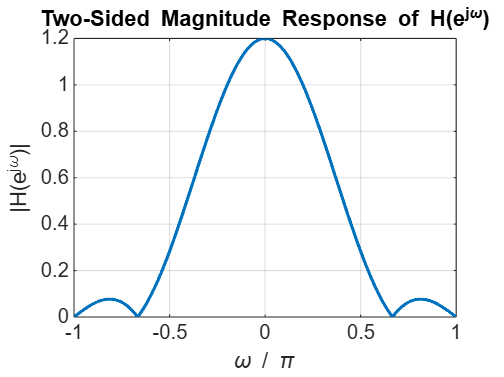

%% Part I

h = [0.2 0.4 0.4 0.2];

% Compute frequency response (0 to pi)
[H, w] = freqz(h, 1, 512);      
mag = abs(H);


% Plot 1: Two-sided magnitude response (-pi to pi)

[H_pos, w_pos] = freqz(h, 1, 512);
H_full = [flipud(conj(H_pos(2:end))); H_pos];    % Mirror for negative frequencies
w_full = [-flipud(w_pos(2:end)); w_pos];

figure;
plot(w_full/pi, abs(H_full), 'LineWidth', 1.5);
xlabel('\omega / \pi');
ylabel('|H(e^{j\omega})|');
title('Two-Sided Magnitude Response of H(e^{j\omega})');
grid on;

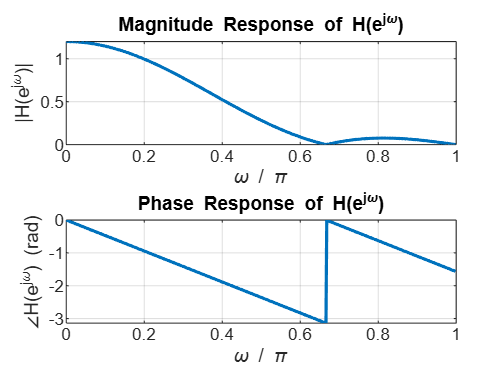



% Plot 2: Single-sided magnitude and phase response

figure;
subplot(2,1,1);
plot(w/pi, abs(H), 'LineWidth', 1.5);
xlabel('\omega / \pi');
ylabel('|H(e^{j\omega})|');
title('Magnitude Response of H(e^{j\omega})');
grid on;

subplot(2,1,2);
plot(w/pi, angle(H), 'LineWidth', 1.5);
xlabel('\omega / \pi');
ylabel('∠H(e^{j\omega}) (rad)');
title('Phase Response of H(e^{j\omega})');
grid on;



% Find cutoff frequency (magnitude drops below 0.707 * peak)

peak = max(mag);
threshold = 0.707 * peak;
index_cutoff = find(mag <= threshold, 1);
w_cutoff = w(index_cutoff);                 % in radians/sample
w_norm = w_cutoff / (2*pi);                 % normalized (cycles/sample)


% Convert to Hz under two sampling rates

fs1 = 4000;
fs2 = 8000;
fc1 = w_norm * fs1;
fc2 = w_norm * fs2;


% Output results

fprintf('Peak magnitude: %.4f\n', peak);

Peak magnitude: 1.2000


fprintf('Cutoff frequency in rad/sample: %.4f\n', w_cutoff);

Cutoff frequency in rad/sample: 0.8468


fprintf('Normalized cutoff frequency (cycles/sample): %.4f\n', w_norm);

Normalized cutoff frequency (cycles/sample): 0.1348


fprintf('Cutoff frequency for fs = %d Hz: %.2f Hz\n', fs1, fc1);

Cutoff frequency for fs = 4000 Hz: 539.06 Hz


fprintf('Cutoff frequency for fs = %d Hz: %.2f Hz\n', fs2, fc2);

Cutoff frequency for fs = 8000 Hz: 1078.12 Hz


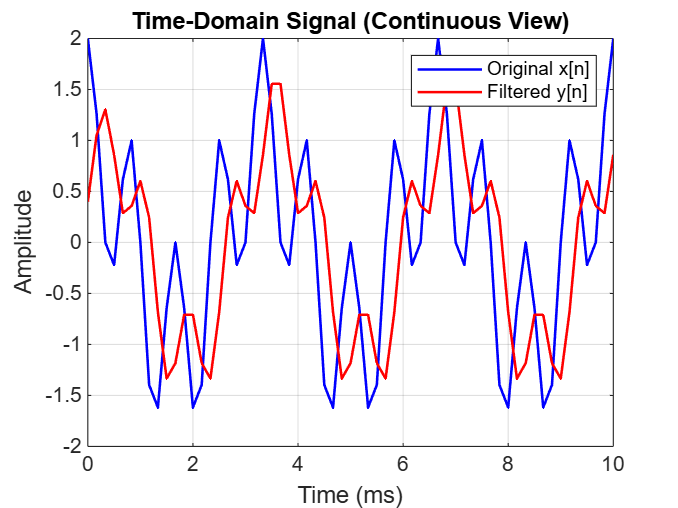

%% Part II

fs = 6000;
t = 0:1/fs:0.01;
x300 = cos(2*pi*300*t);
x1200 = cos(2*pi*1200*t);
x = x300 + x1200;
h = [0.2 0.4 0.4 0.2];
y300 = filter(h, 1, x300);
y1200 = filter(h, 1, x1200);
y = filter(h, 1, x);
n300 = 0:length(x300)-1;
n1200 = 0:length(x1200)-1;
n = 0:length(x)-1;


% Figure 1: Time-domain waveform (continuous-time view)

figure;
plot(t*1000, x, 'b', 'LineWidth', 1.2); hold on;
plot(t*1000, y, 'r', 'LineWidth', 1.2);
legend('Original x[n]', 'Filtered y[n]');
xlabel('Time (ms)');
ylabel('Amplitude');
title('Time-Domain Signal (Continuous View)');
grid on;

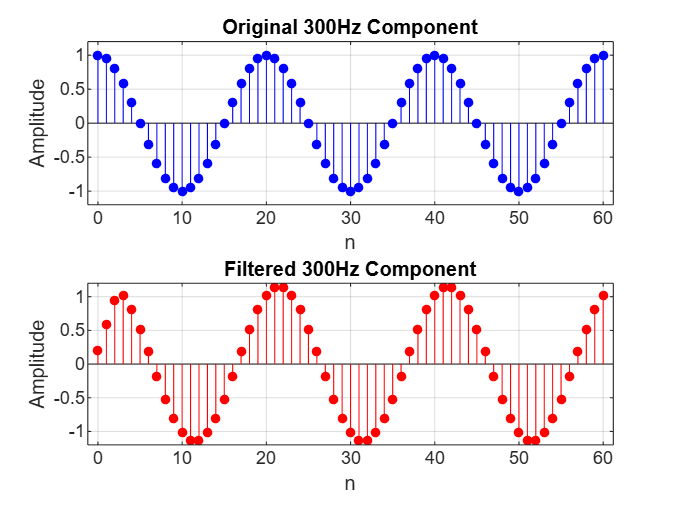



% Plot: Discrete-time 300Hz component

figure;

subplot(2,1,1);
stem(n300, x300, 'b', 'filled', 'MarkerSize', 4);
xlabel('n'); ylabel('Amplitude');
title('Original 300Hz Component');
ylim([-1.2 1.2]); grid on;

subplot(2,1,2);
stem(n300, y300, 'r', 'filled', 'MarkerSize', 4);
xlabel('n'); ylabel('Amplitude');
title('Filtered 300Hz Component');
ylim([-1.2 1.2]); grid on;

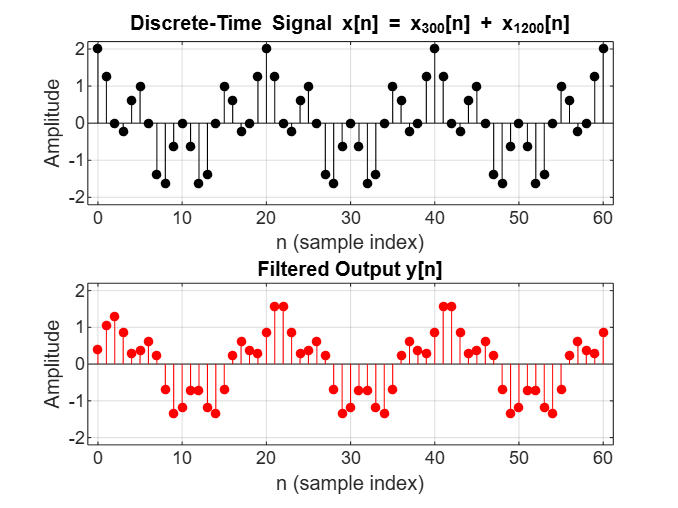



% Plot: Discrete-time 1200Hz component

figure;

subplot(2,1,1);
stem(n1200, x1200, 'm', 'filled', 'MarkerSize', 4);
xlabel('n'); ylabel('Amplitude');
title('Original 1200Hz Component');
ylim([-1.2 1.2]); grid on;

subplot(2,1,2);
stem(n1200, y1200, 'r', 'filled', 'MarkerSize', 4);
xlabel('n'); ylabel('Amplitude');
title('Filtered 1200Hz Component');
ylim([-1.2 1.2]); grid on;


% Plot: Discrete-time Combined Signal x[n]

subplot(2,1,1);
stem(n, x, 'k', 'filled', 'MarkerSize', 4);
xlabel('n (sample index)');
ylabel('Amplitude');
title('Discrete-Time Signal x[n] = x_{300}[n] + x_{1200}[n]');
ylim([-2.2 2.2]);
grid on;


% Plot: Discrete-time Filtered Output y[n]

subplot(2,1,2);
stem(n, y, 'r', 'filled', 'MarkerSize', 4);
xlabel('n (sample index)');
ylabel('Amplitude');
title('Filtered Output y[n]');
ylim([-2.2 2.2]);
grid on;

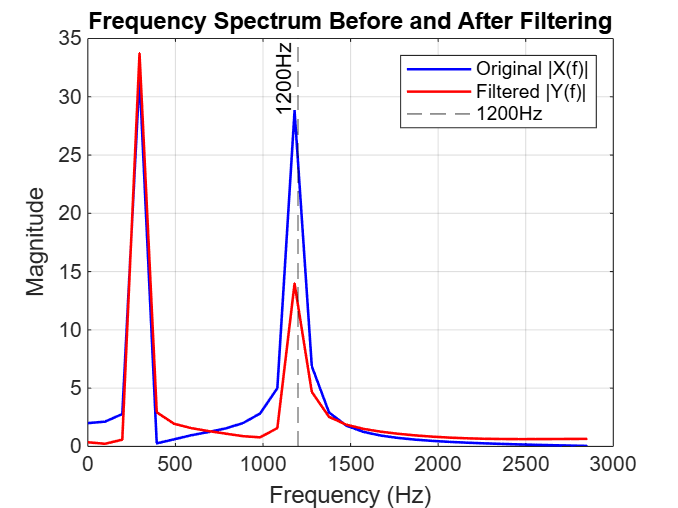



% Figure 3: Frequency spectrum using FFT

N = length(x);                        % Signal length
f_fft = (0:N-1)*(fs/N);               % Frequency axis (Hz)
X = abs(fft(x));                      % FFT of original signal
Y = abs(fft(y));                      % FFT of filtered signal

figure;
plot(f_fft(1:floor(N/2)), X(1:floor(N/2)), 'b', 'LineWidth', 1.2); hold on;
plot(f_fft(1:floor(N/2)), Y(1:floor(N/2)), 'r', 'LineWidth', 1.2);
xline(1200, '--k', '1200Hz', 'LabelHorizontalAlignment','left');
legend('Original |X(f)|', 'Filtered |Y(f)|', '1200Hz');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum Before and After Filtering');
grid on;

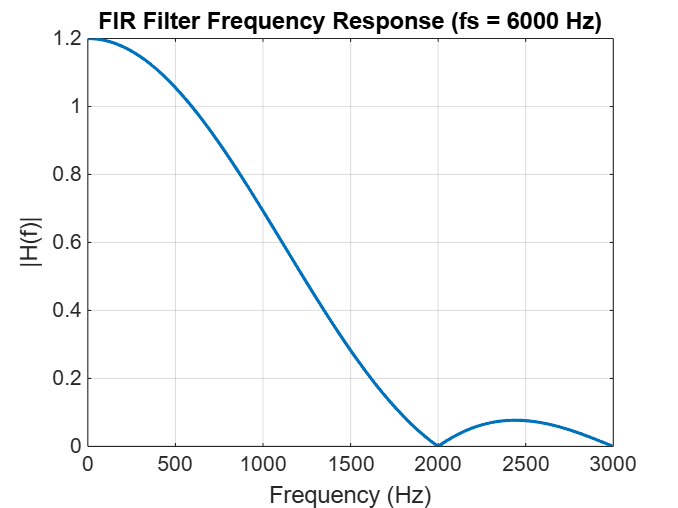



% Figure 4: Frequency response of FIR filter using freqz

[H, f] = freqz(h, 1, 512, fs);        % Frequency response (Hz axis)

figure;
plot(f, abs(H), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title(['FIR Filter Frequency Response (fs = ', num2str(fs), ' Hz)']);
grid on;

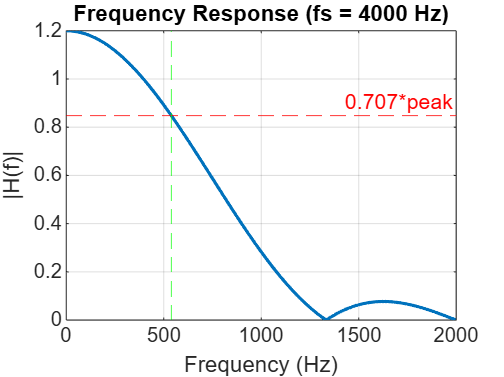

Sampling Rate: 4000 Hz


Cutoff Frequency (fc): 539.06 Hz



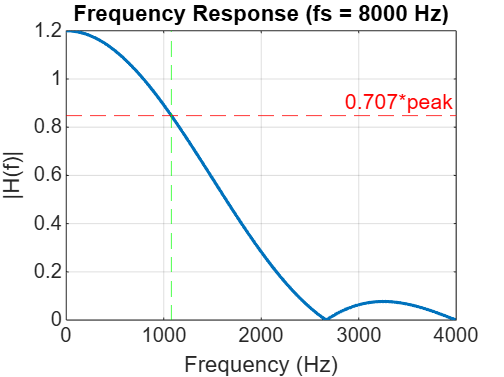

Sampling Rate: 8000 Hz


Cutoff Frequency (fc): 1078.12 Hz



%% Part III
% FIR filter coefficients
h = [0.2 0.4 0.4 0.2];

% Sampling rates
fs_values = [4000, 8000];

for i = 1:length(fs_values)
    fs = fs_values(i);

    % Compute frequency response (in Hz)
    [H, f] = freqz(h, 1, 512, fs);
    mag = abs(H);

    % Find cutoff frequency (0.707 of peak)
    peak = max(mag);
    threshold = 0.707 * peak;
    idx_cutoff = find(mag <= threshold, 1);
    fc = f(idx_cutoff);  % actual cutoff frequency in Hz

    % Plot (each in separate figure)
    figure;
    plot(f, mag, 'LineWidth', 1.5); hold on;
    yline(threshold, '--r', '0.707*peak');  % horizontal line
    xline(fc, '--g');  % label cutoff
    title(['Frequency Response (fs = ', num2str(fs), ' Hz)']);
    xlabel('Frequency (Hz)');
    ylabel('|H(f)|');
    grid on;

    % Print cutoff info to console
    fprintf('Sampling Rate: %d Hz\n', fs);
    fprintf('Cutoff Frequency (fc): %.2f Hz\n\n', fc);
end